%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                  *DATASET CHOICE*                  %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cityStrings = ["Berlin", "Paris", "Rome", "Tokyo", "TestSet"];

%SM: Choose a city
city = cityStrings(1)

city = "Berlin"


%SM: Check any optional parameters
popularity = false;
price = false;
visiting_time = false;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%               *NECCESSARY LOAD_INS*                %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%ST: This will call the dataSet function and return the chosen data set
destSights = getCityDataSet(city);
%ST: Using our own eta instead of euclidean distance
eta = getCityEta(city);
%ST: Using the cost matrix as an additional metric
costs = getCityCosts(city);

%ST: Optional: Display the data set with descriptions
%figure(1);
%text([destSights(:).lat],[destSights(:).long],[destSights(:).name])
%hold on;
%plot([destSights(:).lat],[destSights(:).long],'bo-')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%               *PARAMETER EXPLANATION*              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                    %
%   numAnts = The number of ants in our system.      %
%   maxIts  = The number of iterations our ACO will  %
%             complete.                              %
%   Q       = A constant that is used when updating  %
%             the global pheromone levels.           %
%   rho     = The global pheromone evaporation rate. %
%   tau     = The pheromone matrix.                  %
%   eta     = The distance matrix. In this case      %
%             distances are the travel times needed  %
%             to get from point x to point y.        %
%   costs   = The cost matrix.                       %
%   alpha,                                           %
%   beta,                                            %
%   gamma   = The weighing parameters used to        %
%             control the influence from the         %
%             different matrices, where alpha is     %
%             always 1 - sum(others).                %
%                                                    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%             *SETTING PARAMETER VALUES*             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%numAnts = 25;
%beta = .030;
%maxIts = 1000;
%Q = 100;
%rho = .5;

q_0 = 0.12; % approx. new best at 0.12;
numAnts = 26; % approx. new best at 26;
beta = 3; %approx. new best at 0.01; WHY IS THAT??????????
gamma = 0;
alpha = 1;
maxIts = 2000; %approx. new best at 950;
Q = 10; %approx. new best at 14
rho = 0.5; %approx. new best at 0.22

%ST: Output starting information 
params = struct('q_0', q_0, 'numAnts', numAnts, 'alpha', alpha, 'beta', beta,...
'gamma', gamma, 'Q', Q, 'rho', rho);
fprintf('Running ' + city + ' Sightseeing Optimization on  %i Sights with the following parameters:\n', length(destSights));

Running Berlin Sightseeing Optimization on  11 Sights with the following parameters:


disp(params);

        q_0: 0.1200
    numAnts: 26
      alpha: 1
       beta: 3
      gamma: 0
          Q: 10
        rho: 0.5000




% Tau will be populated dynamically, blank for now
tau = ones(length(destSights),length(destSights));

% Creates an ititial path
bestPath = 1:length(destSights);
bestScore = newScorePath(0, bestPath, destSights, eta);
fprintf('Initial Score: %f', bestScore);

Initial Score: 144.000000


%JT: plot([destSights(:).lat],[destSights(:).long])

numIts = 1;
scores = zeros(1, maxIts);

while numIts < maxIts
	% for every ant_k in colony
	for ant_k = 1:numAnts
		
		% Init empty path and place ant_k at a random starting location
		path = zeros(1, length(destSights));
		currInd = 1;
		path(currInd) = randi(length(destSights));
		
		% Unvisited array consists of all cities ant_k has not yet visited
		unvisited = 1:length(destSights);
		unvisited(path(1)) = [];
		
		% While ant_k has not visited all cities
		for currInd = 1:(length(destSights) - 1)
			r = path(currInd);
			
			% Next destination of ant_k is chosen here.
            % The eta and additional matrices are always 1./matrix
            % due to the fact that bigger travel times or values are
            % supposed to be reflected by smaller values
            % 1/2 -> 0.5, where 1/10 -> 0.1
            % 
				vec = (tau(r, unvisited).^alpha) .* ((1.0 ./ eta(r, unvisited)).^beta) .* ((1.0 ./ costs(r, unvisited)).^gamma);
				probs = vec ./ sum(vec);
				
				% Sometimes prob vec is a zero vector, giving nans. In
				% this case they are all equally bad so we choose 1st
				if any(isnan(probs))
					sInd = 1;
				else
					
					% Draws the city to visit based on the above probabilities:
					%    The ways this works is that the ith element of probs
					%    defines the probability of selecting ith element of
					%    unvisited array. Thus if we want to draw an element
					%    based on this distribution, we treat the probabilities
					%    as a partitioning of the unit interval. We then choose
					%    a partition by generating a random number and then
					%    selecting the interval in which the number lies. By
					%    taking the cumulative sum of the probabilities, we get
					%    the partitions of the unit interval. We then compare
					%    this to the random number, the first nonzero element
					%    of the resulting logical array is the chosen element
					%    of the unvisited array
					sInd = find(cumsum(probs) > rand, 1);
				end
				s = unvisited(sInd);
			
			% Add s to the path and remove it from the unvisited list
			path(currInd + 1) =  s;
			unvisited(sInd) = [];
		end
		
        % test if the current score is better than the current BEST score.
        % If yes, assign the current score as the new bestScore.
		score = newScorePath(0, path, destSights, eta);
		if (score < bestScore)
			bestScore = score;
			bestPath = path;
		end
		
        % this circshift is used to use the same index in the following
        % for loop
		toCities = circshift(path, [0,1]);
		
        % The tau matrix gets updated with the pheromones left by ant_k on
        % its specific path:
		for ind = 1:length(destSights)
			fromCity = path(ind);
			toCity = toCities(ind);
			tau(fromCity, toCity) = tau(fromCity, toCity) + Q / score;
		end
    end
	scores(numIts) = bestScore;
	% Perform the pheromone evaporation
	tau = (1 - rho) * tau;
	
	numIts = numIts + 1;
end

%ST: Display best score at the end, as well as plot the best score with labels.
disp("Best Score: " + bestScore);

Best Score: 103


disp(bestPath)

     5     7     8     9     6    10    11     1     3     2     4



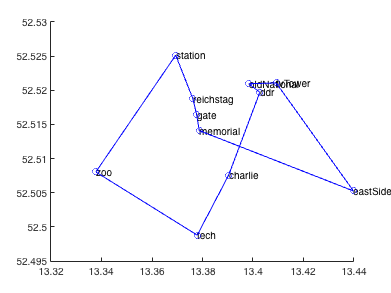

figure(2);
text([destSights(:).lat],[destSights(:).long],[destSights(:).name])
hold on;
plot([destSights(bestPath).lat destSights(bestPath(1)).lat],  [destSights(bestPath).long destSights(bestPath(1)).long], 'bo-');

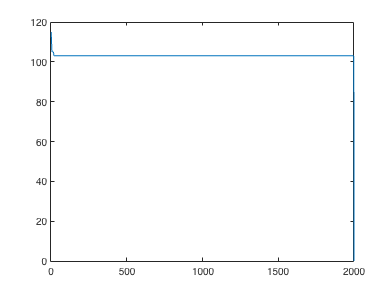


% ST: Plot the scores with their corresponding Iterations, to visualize the
% optimization over time
figure(3);
plot(1:maxIts, scores);